clear all;
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

%-----------------------------------
% Exp3 vs Exp4 GRI
%-----------------------------------
Exp3_path = strcat(Datapath,'Exp3_data.mat');
Exp4_path = strcat(Datapath,'Exp4_data.mat');
analyzer = DataAnalyzer(ana_result,{Exp3_path,'VR-ON'},{Exp4_path,'VR-OFF'});

DataAnalyzerクラスのインスタンスを作成中...
データセット "VR-ON" をロードしています...
  - ファイル: ./data/Exp3_data.mat
  -> ロード成功
データセット "VR-OFF" をロードしています...
  - ファイル: ./data/Exp4_data.mat
  -> ロード成功
インスタンスの作成が完了しました。



% 0. データセット宣言
specA.SetName = 'VR-ON'; 
specB.SetName = 'VR-OFF';

%-----------------------------------
% Exp3 vs Exp4 GRI same subject
%-----------------------------------
Exp3_path = strcat(Datapath,'Exp3_same_subject_data.mat');
Exp4_path = strcat(Datapath,'Exp4_same_subject_data.mat');
analyzer = DataAnalyzer(ana_result,{Exp3_path,'VR-ON'},{Exp4_path,'VR-OFF'});

% 0. データセット宣言
specA.SetName     = 'VR-ON'; 
specB.SetName     = 'VR-OFF';

%-----------------------------------
% Inoue vs Exp3 GRI
%-----------------------------------
Inoue_path = strcat(Datapath,'Inoue_data.mat');
Exp3_path = strcat(Datapath,'Exp3_data.mat');
analyzer = DataAnalyzer(ana_result,{Inoue_path,'Display'},{Exp3_path,'HMD-VRON'});

% 0. データセット宣言
specA.SetName     = 'Display'; 
specB.SetName     = 'HMD-VRON';

%-----------------------------------
% Inoue vs Exp4 GRI
%-----------------------------------
Inoue_path = strcat(Datapath,'Inoue_data.mat');
Exp4_path = strcat(Datapath,'Exp4_data.mat');
analyzer = DataAnalyzer(ana_result,{Inoue_path,'Display'},{Exp4_path,'HMD-VROFF'});

% 0. データセット宣言
specA.SetName     = 'Display'; 
specB.SetName     = 'HMD-VROFF';

% 1. Frequency
specA.TargetData  = 'RowHMSPT'; 
specB.TargetData  = 'RowHMSPT';

analyzer.plotHistogram(specA,0);
analyzer.plotHistogram(specA,1);

analyzer.plotHistogram(specB,0);
analyzer.plotHistogram(specB,1);

% 2. Scatter - GRI
specA.TargetData  = 'ZsH'; 
specA.ErrorData   = 'error_ZsH'; 
specB.TargetData  = 'ZsH';
specB.ErrorData   = 'error_ZsH';
analyzer.plotScatter(specA,specB, ...
    "Property","GRI","HdrSet","HDRNum_30","Amp",1.0,"PreDim",1,"Mode","H","Residual","regression");

specA.TargetData  = 'ZsHM'; 
specA.ErrorData   = 'error_ZsHM';
specB.TargetData  = 'ZsHM';
specB.ErrorData   = 'error_ZsHM';
analyzer.plotScatter(specA,specB,"Mode","HM","Amp",0.6,"Residual","regression");

specA.TargetData  = 'ZsHS'; 
specA.ErrorData   = 'error_ZsHS';
specB.TargetData  = 'ZsHS';
specB.ErrorData   = 'error_ZsHS';
analyzer.plotScatter(specA,specB,"Mode","HS","Amp",0.6,"Residual","regression");

specA.TargetData  = 'ZsHMS'; 
specA.ErrorData   = 'error_ZsHMS';
specB.TargetData  = 'ZsHMS';
specB.ErrorData   = 'error_ZsHMS';
analyzer.plotScatter(specA,specB,"Mode","HMS","Amp",0.6,"Residual","regression");


% 2.5. Residual Scatter - GRI
specA.TargetData  = 'ZsH'; 
specA.ErrorData   = 'error_ZsH'; 
specB.TargetData  = 'ZsH';
specB.ErrorData   = 'error_ZsH';
analyzer.plotScatter(specA,specB, ...
    "Property","GRI","HdrSet","HDRNum_30","Amp",1.0,"PreDim",1,"Mode","H","Residual","outlier");

specA.TargetData  = 'ZsHM'; 
specA.ErrorData   = 'error_ZsHM';
specB.TargetData  = 'ZsHM';
specB.ErrorData   = 'error_ZsHM';
analyzer.plotScatter(specA,specB,"Mode","HM","Amp",0.6,"Residual","outlier");

specA.TargetData  = 'ZsHS'; 
specA.ErrorData   = 'error_ZsHS';
specB.TargetData  = 'ZsHS';
specB.ErrorData   = 'error_ZsHS';
analyzer.plotScatter(specA,specB,"Mode","HS","Amp",0.6,"Residual","outlier");

specA.TargetData  = 'ZsHMS'; 
specA.ErrorData   = 'error_ZsHMS';
specB.TargetData  = 'ZsHMS';
specB.ErrorData   = 'error_ZsHMS';
analyzer.plotScatter(specA,specB,"Mode","HMS","Amp",0.6,"Residual","outlier");

% 2. Scatter - gloss
specA.TargetData  = 'RowH'; 
specA.ErrorData   = 'error_ZsH'; 
specB.TargetData  = 'RowH';
specB.ErrorData   = 'error_ZsH';
analyzer.plotScatter(specA,specB, ...
    "Property","Gross","HdrSet","HDRNum_30","Amp",1.5,"PreDim",1,"Mode","H","Residual","outlier");


specA.TargetData  = 'RowHM'; 
specA.ErrorData   = 'error_ZsHM';
specB.TargetData  = 'RowHM';
specB.ErrorData   = 'error_ZsHM';
analyzer.plotScatter(specA,specB,"Property",'Gross',"Mode","HM","Amp",0.6);

specA.TargetData  = 'RowHS'; 
specA.ErrorData   = 'error_ZsHS';
specB.TargetData  = 'RowHS';
specB.ErrorData   = 'error_ZsHS';
analyzer.plotScatter(specA,specB,"Property",'Gross',"Mode","HS","Amp",0.6);

specA.TargetData  = 'RowHMS'; 
specA.ErrorData   = 'error_ZsHMS';
specB.TargetData  = 'RowHMS';
specB.ErrorData   = 'error_ZsHMS';
analyzer.plotScatter(specA,specB,"Property",'Gross',"Mode","HMS","Amp",0.6);

% 3. Significance
specA.TargetData = 'RowHMSPT';
specB.TargetData = 'RowHMSPT';
numBootstrap = 10000;
numSplit = 1;
Distribution_Flag = true;
analyzer.plotCorrBootstrap(specA,specB,"Mode","H","Bootstrap",numBootstrap,"Split",numSplit,"Amp",1.3,...
    "Distribution",Distribution_Flag);

相関係数のBootstrapを実行中 (Mode: H)...

観測された相関 corr(A, B): 0.9660
データAAのCI95: 0.995, 0.999
データABのCI95: 0.942, 0.981
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


  -> 各種グラフを保存しました
プロットの作成が完了しました。



analyzer.plotCorrBootstrap(specA,specB,"Mode","HM","Bootstrap",numBootstrap,"Split",numSplit,"Amp",1.0,...
    "Distribution",Distribution_Flag);

相関係数のBootstrapを実行中 (Mode: HM)...
cu-0.025
観測された相関 corr(A, B): 0.9188
データAAのCI95: 0.961, 0.994
データABのCI95: 0.808, 0.951
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


cu-0.129
観測された相関 corr(A, B): 0.9321
データAAのCI95: 0.977, 0.996
データABのCI95: 0.836, 0.967
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


pla-0.075
観測された相関 corr(A, B): 0.9608
データAAのCI95: 0.988, 0.998
データABのCI95: 0.916, 0.979
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


pla-0.225
観測された相関 corr(A, B): 0.9436
データAAのCI95: 0.990, 0.998
データABのCI95: 0.890, 0.967
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


  -> 各種グラフを保存しました
プロットの作成が完了しました。



analyzer.plotCorrBootstrap(specA,specB,"Mode","HS","Bootstrap",numBootstrap,"Split",numSplit,"Amp",1.0,...
    "Distribution",Distribution_Flag);

相関係数のBootstrapを実行中 (Mode: HS)...
sphere
観測された相関 corr(A, B): 0.9636
データAAのCI95: 0.978, 0.996
データABのCI95: 0.900, 0.977
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


bunny
観測された相関 corr(A, B): 0.9251
データAAのCI95: 0.976, 0.996
データABのCI95: 0.844, 0.960
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


dragon
観測された相関 corr(A, B): 0.9417
データAAのCI95: 0.979, 0.997
データABのCI95: 0.862, 0.965
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


boardA
観測された相関 corr(A, B): 0.7945
データAAのCI95: 0.958, 0.994
データABのCI95: 0.657, 0.887
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


boardB
観測された相関 corr(A, B): 0.9438
データAAのCI95: 0.987, 0.998
データABのCI95: 0.888, 0.976
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


boardC
観測された相関 corr(A, B): 0.9534
データAAのCI95: 0.983, 0.997
データABのCI95: 0.876, 0.969
p値: 0.000
結論: corr(A,B)はノイズ天井よりも有意に低いです


  -> 各種グラフを保存しました
プロットの作成が完了しました。



analyzer.plotCorrBootstrap(specA,specB,"Mode","HMS","Bootstrap",numBootstrap,"Split",numSplit,...
    "Distribution",Distribution_Flag);

%4 Residuals
specA.TargetData = 'ZsH';
specB.TargetData = 'ZsH';
analyzer.plotResiduals(specA,specB,"Property",'GRI',"Amp",1.5);

specA.TargetData = 'ZsHM';
specB.TargetData = 'ZsHM';
analyzer.plotResiduals(specA,specB,"Property",'GRI',"Amp",1.5,'Mode',2);

specA.TargetData = 'ZsHS';
specB.TargetData = 'ZsHS';
analyzer.plotResiduals(specA,specB,"Property",'GRI',"Amp",1.5,'Mode',3);

specA.TargetData = 'ZsHMS';
specB.TargetData = 'ZsHMS';
analyzer.plotResiduals(specA,specB,"Property",'GRI',"Amp",1.5);

specA.TargetData = 'RowH';
specB.TargetData = 'RowH';
analyzer.plotResiduals(specA,specB,"Property",'Gross',"Amp",1.5);

ANOVAを実行中 (Mode: H)...


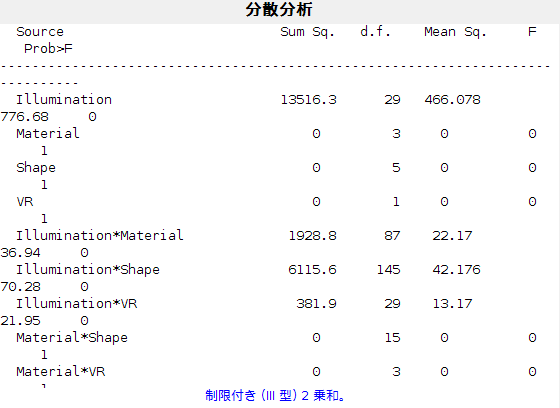

ANOVA表をCSVに保存しました: analysis/VR-ONvsVR-OFF_GRI_Anova.csv
ANOVAが完了しました。


%5. ANOVA
specA.TargetData = 'RowHMSPT';
specB.TargetData = 'RowHMSPT';
factor_names = ["Illumination", "Material", "Shape", "VR"];

analyzer.ANOVA(specA,specB,"FactorNames", factor_names);